# Realisation: from Transfer Functions to a State-Space Representation for SISO Systems

## Introduction

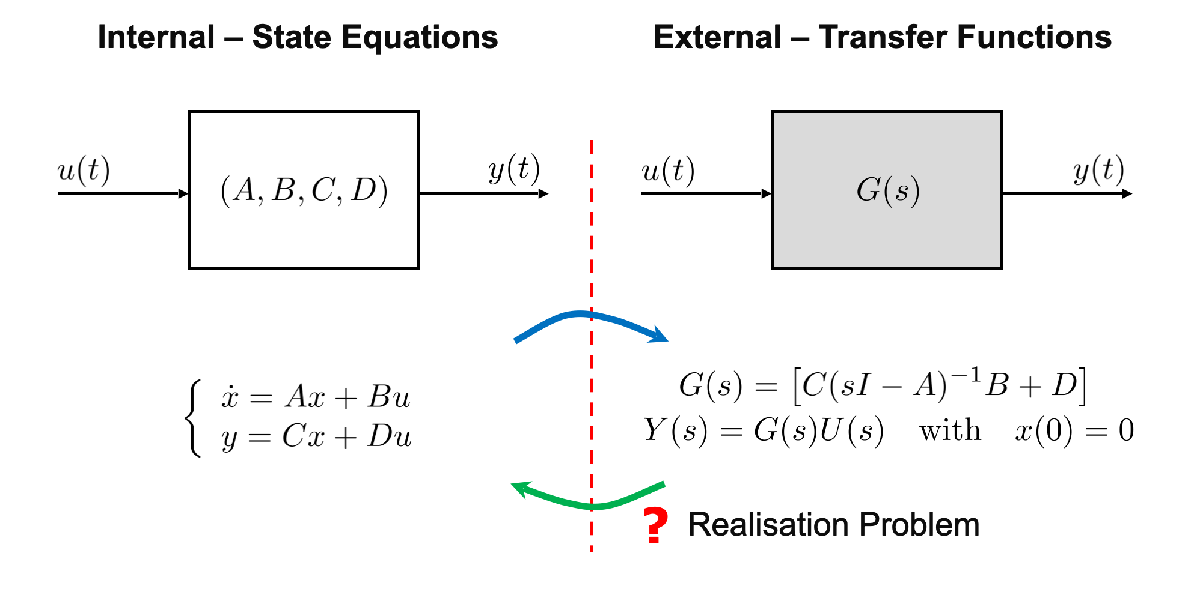

See Part 4 of the course material.

By exploring this live script, you will learn how to use the Symbolic Math Toolbox to calculate a few state space representation of a SISO dynamic system, given the transfer function.

## Example 1: a Strictly Proper SISO System

Consider the SISO system described by the transfer function


$$G_1(s) = \frac{1}{12 s^2+48 s +120} = \frac{1}{12} \cdot \frac{1}{s^2+4s+10}$$


### The LTI system as a Transfer Function using the Control System Toolbox

We may define such a system in MATLAB as an **LTI object** using the functions `tf( )` or `zpk( )`

clear

% the system as a TF LTI object
G1sTF = tf([1/12], [1  4  10]) 


G1sTF =
 
     0.08333
  --------------
  s^2 + 4 s + 10
 
Continuous-time transfer function.
Model Properties



% the system as a ZPK LTI object
G1zeros = [];                % no zeros
G1poles = roots([1  4  10]); % the poles of G1(s)
G1gain = 1/12;               % the gain constant <-- pay attention!
                             %                       it is NOT the
                             %                       static gain
G1sZPK = zpk(G1zeros, G1poles, G1gain)


G1sZPK =
 
     0.083333
  ---------------
  (s^2 + 4s + 10)
 
Continuous-time zero/pole/gain model.
Model Properties


As you note, both the MATLAB objects describe the same LTI system.

### Realisation: from the Transfer Function to a State Space Realisation 

#### Using the Symbolic Math Toolbox

Let's define the system $G_1(s)$ using the Symbolic Math Toolbox:

syms s     % the complex frequency variable for the Laplace transform
syms G1sSYS % the symbolic object describing the transfer function G1(s)

G1sSYS = sym(1/12)*1/(s^2+4*s+10)

$$G1sSYS = \frac{1}{12\,\left(s^{2}+4\,s+10\right)}$$

poles(G1sSYS)

$$ans = \left[\begin{array}{c} -2+\sqrt{6}\,\mathrm{i}\\ -2-\sqrt{6}\,\mathrm{i} \end{array}\right]$$

Define the numerator and denominator polynomials

NsG1SYS = sym(1/12);            % the numerator N(s)
NsCoeffs = coeffs(NsG1SYS, s);  % symbolic array with the coefficients of N(s)

DsG1SYS = (s^2+4*s+10);         % the denominator D(s)
DsCoeffs = coeffs(DsG1SYS, s);  % symbolic array with the coefficients of D(s)


#### Solution 1


$$\left \{
\begin{array}{l}
\left[\begin{array}{c}
      \dot x_1 \\
      \dot x_2 \\
\vdots \\
\dot x_{n-1} \\
\dot x_n
\end{array} \right] =
\left[\begin{array}{ccccc}
      0 & 1 & 0 & \cdots & 0 \\
      0 & 0 & 1 & \cdots & 0 \\
      \vdots & \vdots & \vdots & \ddots & \vdots \\
      0 & 0 & 0 & \cdots & 1 \\
     -\alpha_0 & -\alpha_1 & -\alpha_2 & \cdots & -\alpha_{n-1}
\end{array} \right]
\left[\begin{array}{c}
      x_1 \\
      x_2 \\
\vdots \\
x_{n-1} \\
x_n
\end{array} \right] +
\left[\begin{array}{c}
      0 \\
      0 \\
\vdots \\
0 \\
1
\end{array} \right] u \\
\\
y = 
\left[\begin{array}{ccccccc}
\beta_0 &\beta_1 & \cdots &\beta_m & 0 & \cdots & 0
\end{array} \right] 
\left[\begin{array}{c}
      x_1 \\
      x_2 \\
\vdots \\
x_{n-1} \\
x_n
\end{array} \right]
\end{array}
\right . \\$$


given 


$$G(s) = \frac{
\beta_m s^m +\beta_{m-1} s^{m-1} +
\cdots + \beta_1 s + \beta_0}
{\alpha_n s^n +\alpha_{n-1} s^{n-1} +
\cdots + \alpha_1 s + \alpha_0} \quad \textrm{with} \quad m<n$$


Thus

n = numel(DsCoeffs)-1; % how many state variables? <--> the degree of D(s)
m = numel(NsCoeffs)-1; % the degree of N(s) 

B1mat = sym([zeros(n-1,1); 1])           % the B matrix

$$B1mat = \left[\begin{array}{c} 0\\ 1 \end{array}\right]$$


C1mat = sym([NsCoeffs, zeros(1, n-m-1)]) % the C matrix

$$C1mat = \left[\begin{array}{cc} \frac{1}{12} & 0 \end{array}\right]$$


A1mat = sym([[zeros(n-1,1), eye(n-1)]; ...
                 -DsCoeffs(1:end-1)])          % the A matrix

$$A1mat = \left[\begin{array}{cc} 0 & 1\\ -10 & -4 \end{array}\right]$$

Now we are able to create an LTI object describing the system $G_1(s)$ using a state space representation

A1 = double(A1mat);
B1 = double(B1mat);
C1 = double(C1mat);
D1 = 0; % <-- SISO stricly proper system!

SYS1 = ss(A1, B1, C1, D1) % the 1st state space representation


SYS1 =
 
  A = 
        x1   x2
   x1    0    1
   x2  -10   -4
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
            x1       x2
   y1  0.08333        0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


#### Remark

We may obtain the state space representation starting directly from the `tf( )` representation, without the symbolic computations. 

In facts, it is simple to collect the coefficients of the polynomials in the `tf( )` representation, using the function

[NsTFcoeffs, DsTFcoeffs] = tfdata(G1sTF, 'v')

NsTFcoeffs =          0         0    0.0833


DsTFcoeffs =      1     4    10


#### Solution 2


$$\left \{
\begin{array}{l}
\left[\begin{array}{c}
      \dot x_1 \\
      \dot x_2 \\
\vdots \\
\dot x_{n-1} \\
\dot x_n
\end{array} \right] =
\left[ \begin{array}{ccccc}
      0 & 0 &  \cdots & 0 &-\alpha_0 \\
      1 & 0 &  \cdots & 0 & -\alpha_1 \\
      \vdots & \ddots & \vdots & \vdots & \vdots \\
      0 & \cdots & 1 & 0 & -\alpha_{n-2} \\
      0 & \cdots & 0 & 1 &-\alpha_{n-1}
\end{array}\right]
\left[\begin{array}{c}
      x_1 \\
      x_2 \\
\vdots \\
x_{n-1} \\
x_n
\end{array}\right] +
\left[\begin{array}{c}
   \beta_0 \\
      \beta_1 \\
\vdots \\
\beta_m \\
0 \\
\vdots \\
0
\end{array}\right] u \\
 \\
y = 
\left[ \begin{array}{cccc}
0 & \cdots & 0 & 1
\end{array} \right]
\left[\begin{array}{c}
      x_1 \\
      x_2 \\
\vdots \\
x_{n-1} \\
x_n
\end{array} \right]
\end{array}
\right . \\$$


given 


$$G(s) = \frac{
\beta_m s^m +\beta_{m-1} s^{m-1} +
\cdots + \beta_1 s + \beta_0}
{\alpha_n s^n +\alpha_{n-1} s^{n-1} +
\cdots + \alpha_1 s + \alpha_0} \quad \textrm{with} \quad m<n$$


Thus

n = numel(DsCoeffs)-1; % how many state variables? <--> the degree of D(s)
m = numel(NsCoeffs)-1; % the degree of N(s) 

B2mat = sym([NsCoeffs; zeros(n-m-1, 1)])           % the B matrix

$$B2mat = \left[\begin{array}{c} \frac{1}{12}\\ 0 \end{array}\right]$$


C2mat = sym([zeros(1, n-1), 1]) % the C matrix

$$C2mat = \left[\begin{array}{cc} 0 & 1 \end{array}\right]$$


lastCol_A2 = transpose(DsCoeffs(1:end-1));
A2mat = sym([[zeros(1, n-1); eye(n-1)], ...
                 -lastCol_A2])          % the A matrix

$$A2mat = \left[\begin{array}{cc} 0 & -10\\ 1 & -4 \end{array}\right]$$

Now we are able to create an LTI object describing the system $G_1(s)$ using a state space representation

A2 = double(A2mat);
B2 = double(B2mat);
C2 = double(C2mat);
D2 = 0; % <-- SISO stricly proper system!

SYS2 = ss(A2, B2, C2, D2) % the 2nd state space representation


SYS2 =
 
  A = 
        x1   x2
   x1    0  -10
   x2    1   -4
 
  B = 
            u1
   x1  0.08333
   x2        0
 
  C = 
       x1  x2
   y1   0   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Mo

#### Remark 2

We may obtain the state space representation starting directly from the `tf( )` representation, without the symbolic computations. 

In facts, it is simple to collect the coefficients of the polynomials in the `tf( )` representation, using the function

[NsTFcoeffs, DsTFcoeffs] = tfdata(G1sTF, 'v')

NsTFcoeffs =          0         0    0.0833


DsTFcoeffs =      1     4    10


### Simulating the System

Now we can simulate the behaviour of the system $G_1(s)$ using either the transfer function model or the state space representation.

Please, refer to the live script named "Intro_MATLAB_034IN_FAC_p6.mlx" in the "INTRO_MATLAB_SIMULINK" folder (into the class materials area of the course).

Of course, both models provide the same solution when used correctly. This means considering for both cases only the forced response of the system, i.e. that which is obtained by applying the input $u(t)$ from the initial null state.

#### Forced State and Output Responses

Let's calculate the forced state and output trajectories corresponding to the input 


$$u(t) = \big[3+2\,\sin\left(4 \pi\,t\right) \big] \cdot 1(t)$$


Tmax = 10; % let's simulate the system behaviour in the time interval [0, Tmax]

t = (0:0.001:Tmax); % a vector containing some time instants

u = 3+2*sin(4*pi*t); % the input values -- Notice: we do not apply the Heaviside function!

[y1, ~, x1] = lsim(SYS1, u, t); % evaluate the forced state & output movement 
                                % of the 1st state-space model

[y2, ~, x2] = lsim(SYS2, u, t); % evaluate the forced state & output movement 
                                % of the 2nd state-space model

[yTF, ~] = lsim(G1sTF, u, t); % evaluate the forced state & output movement 
                                % of the TF model                                


#### Comparing the Results

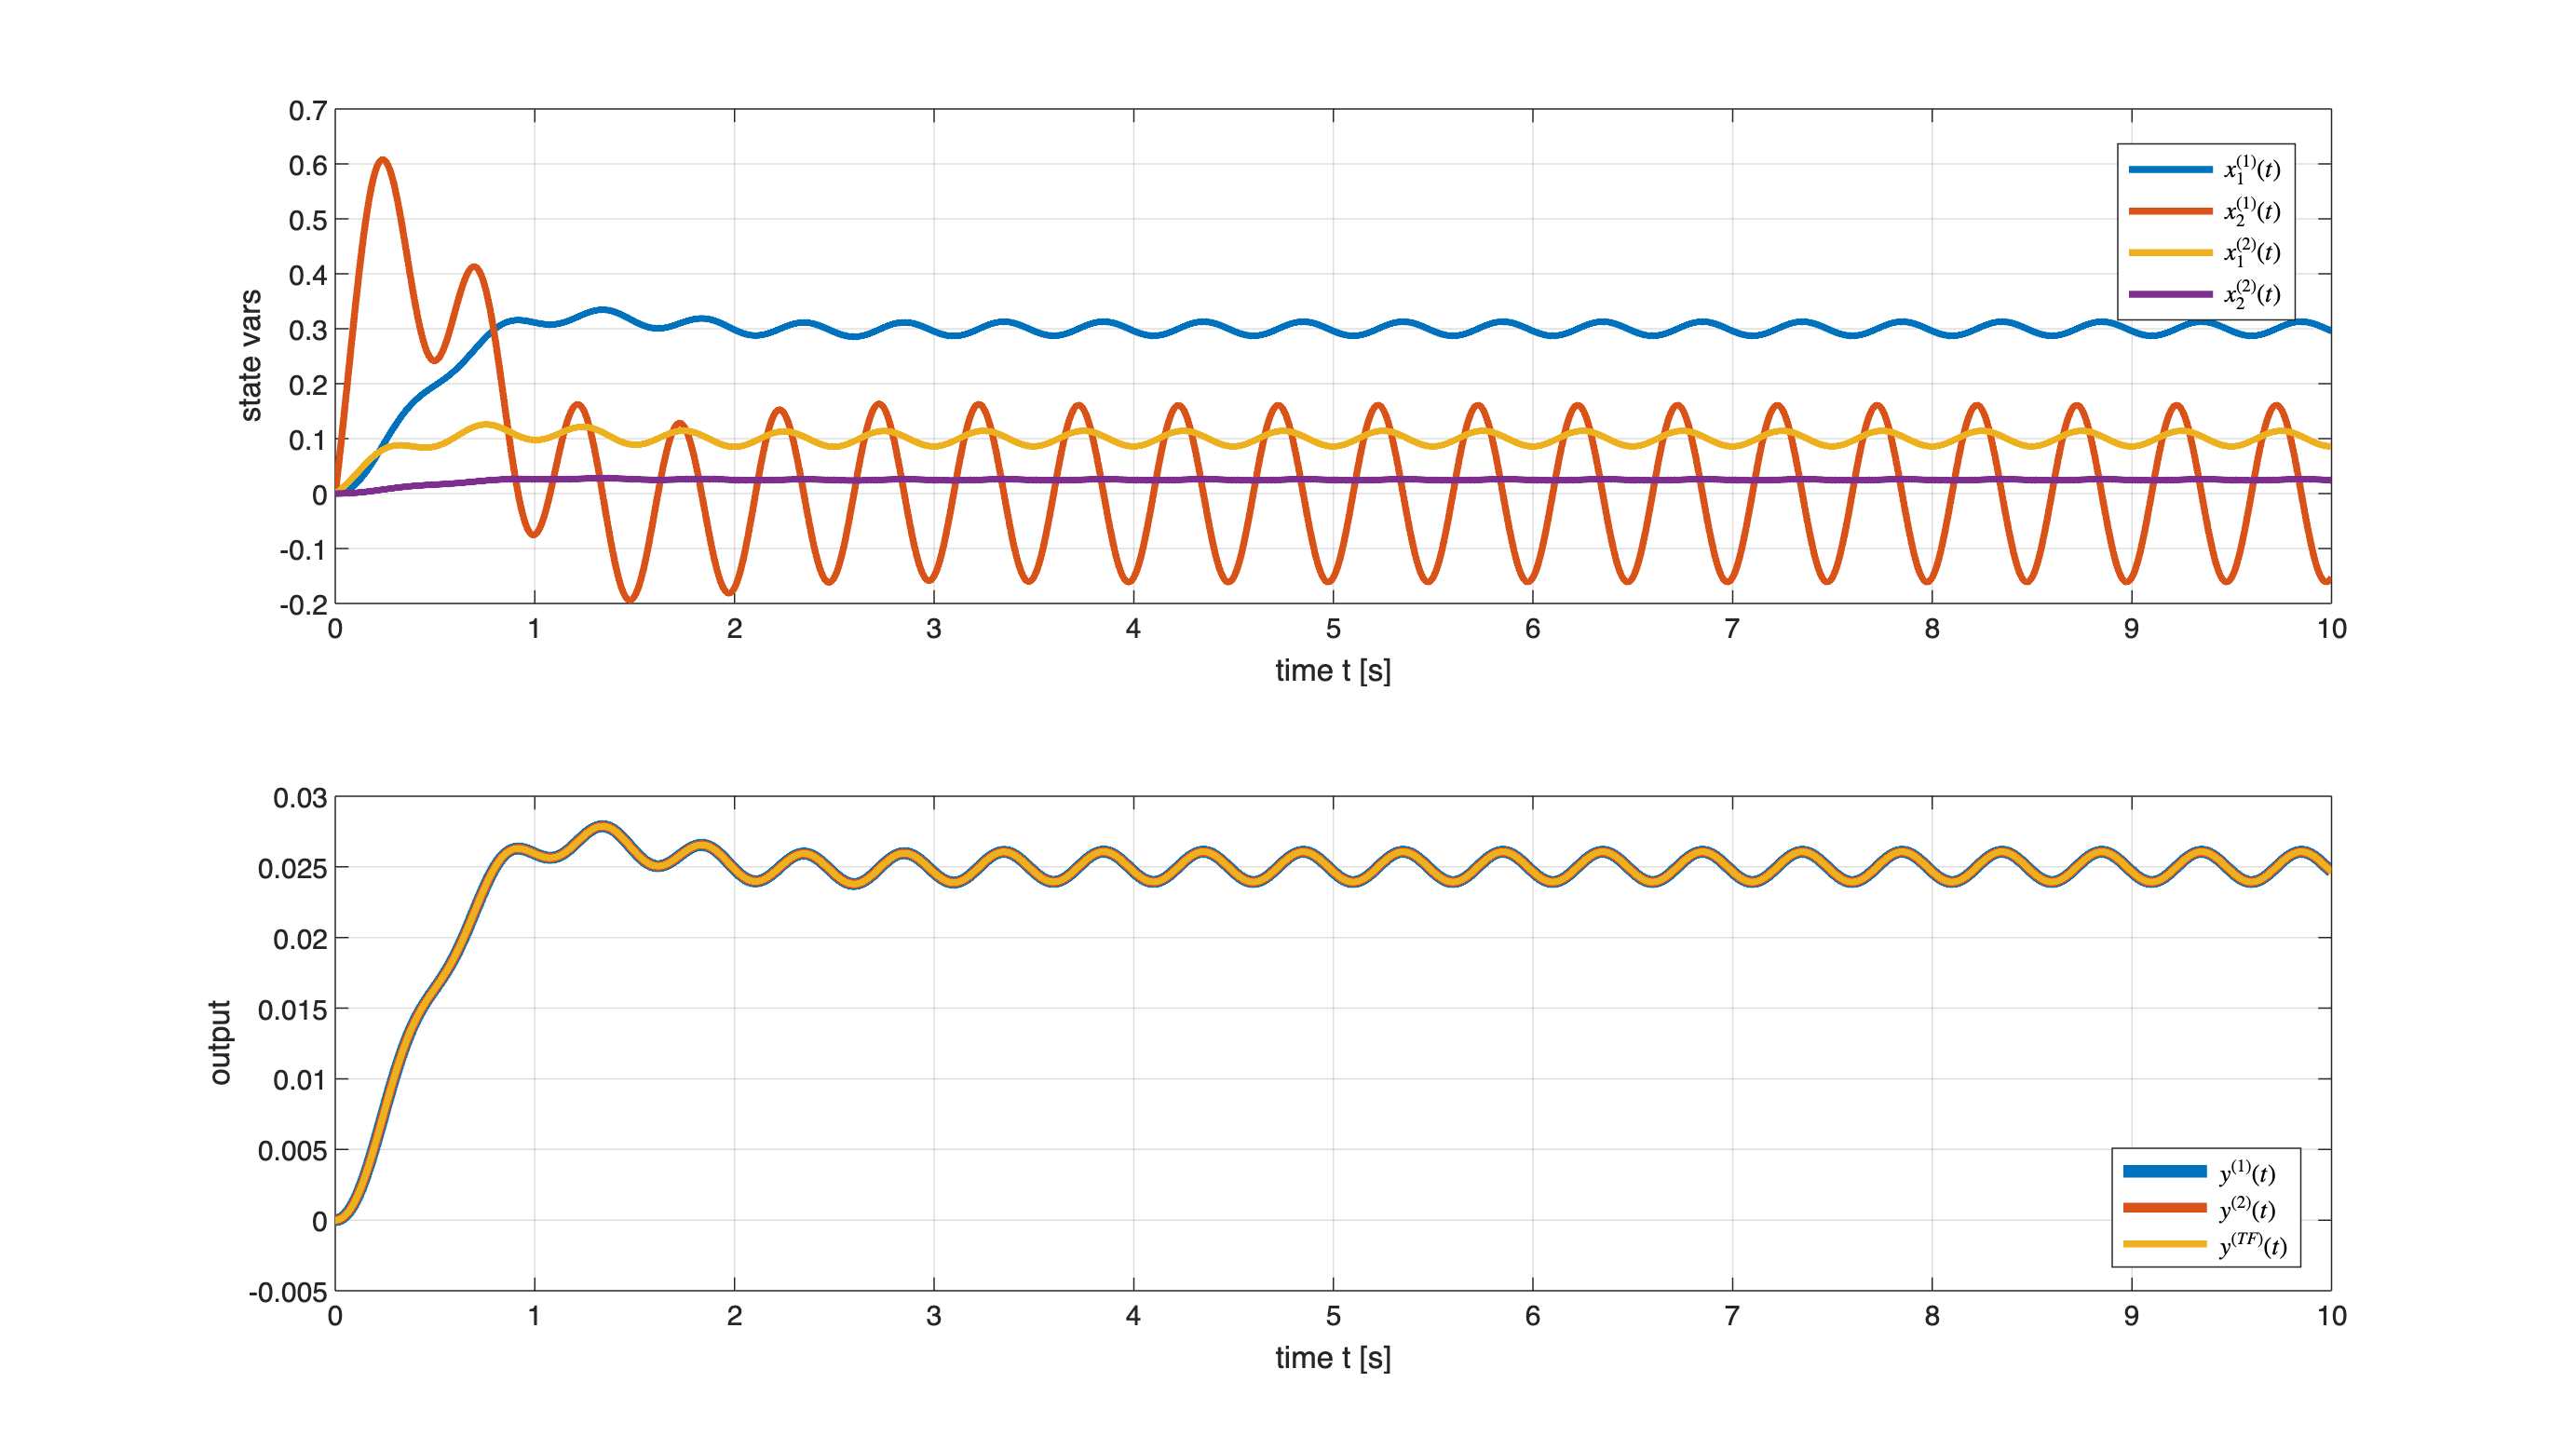

                                
figure('Units','normalized','Position',[0.1, 0.1, 0.9, 0.9]);
subplot(2, 1, 1);
plot(t, x1, 'LineWidth', 2.5);
grid on; hold on
plot(t, x2, 'LineWidth', 2.5);
xlabel('time t [s]'); ylabel('state vars');
legend('$x^{(1)}_{1}(t)$', '$x^{(1)}_{2}(t)$', ...
    '$x^{(2)}_{1}(t)$', '$x^{(2)}_{2}(t)$', ...
    'Interpreter', 'latex','Location', 'best')

subplot(2,1,2);
plot(t,y1, 'LineWidth', 4.5); % plotting the results
grid on; hold on
plot(t,y2, 'LineWidth', 3.5); 
plot(t,yTF, 'LineWidth', 2.5); 
xlabel('time t [s]'); ylabel('output');
legend('$y^{(1)}(t)$', '$y^{(2)}(t)$','$y^{(TF)}(t)$', ...
    'Interpreter', 'latex','Location', 'best')

#### Final Remarks

- The forced state responses of the two models are different! This is due to the different state variables involved in the two models.

- However, the forced output responses of both state-space models are the same as the forced response calculated using the transfer function model (as expected!).

## Example 2: a NOT Strictly Proper SISO System

Consider the SISO system described by the transfer function


$$G_2(s) = \frac{4s^3+12 s^2+8s+10}{s^3+3s^2+2s+1} $$


### The LTI system as a Transfer Function using the Control System Toolbox

We may define such a system in MATLAB as an **LTI object** using the functions `tf( )` or `zpk( )`

clear

% the system as a TF LTI object
G2sTF = tf([4 12 8 10], [1  3  2  1]) 


G2sTF =
 
  4 s^3 + 12 s^2 + 8 s + 10
  -------------------------
    s^3 + 3 s^2 + 2 s + 1
 
Continuous-time transfer function.
Model Properties



% the system as a ZPK LTI object
G2zeros = roots([4 12 8 10]);  % the zeros of G2(s)
G2poles = roots([1  3  2  1]); % the poles of G2(s)
G2gain = 4;                  % the gain constant <-- pay attention!
                             %                       it is NOT the
                             %                       static gain
G2sZPK = zpk(G2zeros, G2poles, G2gain)


G2sZPK =
 
  4 (s+2.601) (s^2 + 0.3994s + 0.9613)
  ------------------------------------
   (s+2.325) (s^2 + 0.6753s + 0.4302)
 
Continuous-time zero/pole/gain model.
Model Properties


tf(G2sZPK)


ans =
 
  4 s^3 + 12 s^2 + 8 s + 10
  -------------------------
    s^3 + 3 s^2 + 2 s + 1
 
Continuous-time transfer function.
Model Properties


As you note, both the MATLAB objects describe the same LTI system.

### Realisation: from the Transfer Function to a State Space Realisation 

#### Using the Symbolic Math Toolbox

Let's define the system $G_2(s)$ using the Symbolic Math Toolbox:

syms s     % the complex frequency variable for the Laplace transform
syms G2sSYS % the symbolic object describing the transfer function G1(s)

G2sSYS = (4*s^3+12*s^2+8*s+10)/(s^3+3*s^2+2*s+1)

$$G2sSYS = \frac{4\,s^{3}+12\,s^{2}+8\,s+10}{s^{3}+3\,s^{2}+2\,s+1}$$

poles(G2sSYS)

$$ans = \left[\begin{array}{c} -0.33764102137762698701954557276095+0.56227951206230124389918214490937\,\mathrm{i}\\ -0.33764102137762698701954557276095-0.56227951206230124389918214490937\,\mathrm{i}\\ -2.3247179572447460259609088544781 \end{array}\right]$$

Define the numerator and denominator polynomials

NsG2SYS = 4*s^3+12*s^2+8*s+10;   % the numerator N(s)
Ns2Coeffs = coeffs(NsG2SYS, s);  % symbolic array with the coefficients of N(s)

DsG2SYS = (s^3+3*s^2+2*s+1);         % the denominator D(s)
Ds2Coeffs = coeffs(DsG2SYS, s);  % symbolic array with the coefficients of D(s)


#### Solution 1


$$\left \{
\begin{array}{l}
\left[\begin{array}{c}
      \dot x_1 \\
      \dot x_2 \\
\vdots \\
\dot x_{n-1} \\
\dot x_n
\end{array} \right] =
\left[\begin{array}{ccccc}
      0 & 1 & 0 & \cdots & 0 \\
      0 & 0 & 1 & \cdots & 0 \\
      \vdots & \vdots & \vdots & \ddots & \vdots \\
      0 & 0 & 0 & \cdots & 1 \\
     -\alpha_0 & -\alpha_1 & -\alpha_2 & \cdots & -\alpha_{n-1}
\end{array} \right]
\left[\begin{array}{c}
      x_1 \\
      x_2 \\
\vdots \\
x_{n-1} \\
x_n
\end{array} \right] +
\left[\begin{array}{c}
      0 \\
      0 \\
\vdots \\
0 \\
1
\end{array} \right] u \\
\\
y = 
\left[\begin{array}{ccccc}
\gamma_0 &\gamma_1 & \cdots &\gamma_{n-2} & \gamma_{n-1}
\end{array} \right] 
\left[\begin{array}{c}
      x_1 \\
      x_2 \\
\vdots \\
x_{n-1} \\
x_n
\end{array} \right] + \frac{\beta_n}{\alpha_n} u
\end{array}
\right . \\$$


given 


$$G(s) = \frac{
\beta_n s^n +\beta_{n-1} s^{n-1} +
\cdots + \beta_1 s + \beta_0}
{\alpha_n s^n +\alpha_{n-1} s^{n-1} +
\cdots + \alpha_1 s + \alpha_0} = \frac{\beta_n}{\alpha_n} + \frac{\gamma_{n-1} s^{n-1}+\gamma_{n-2}s^{n-2} + \cdots + \gamma_1 s + \gamma_0}{\alpha_n s^n +\alpha_{n-1} s^{n-1} +
\cdots + \alpha_1 s + \alpha_0}$$


Thus

% first step: let's divide N(s) by D(s) and compute quotient (beta_n/alpha_n) and reminder  
[gammaPoly, q] = polynomialReduce(NsG2SYS, DsG2SYS, s);
gammaCoeff = coeffs(gammaPoly, s);
n = numel(Ds2Coeffs)-1; % how many state variables? <--> the degree of D(s)
m = numel(gammaCoeff)-1; % the degree of gamma(s) 

D2mat = q;                                % the D matrix      

B2mat = sym([zeros(n-1,1); 1])            % the B matrix

$$B2mat = \left[\begin{array}{c} 0\\ 0\\ 1 \end{array}\right]$$


C2mat = sym([gammaCoeff, zeros(1, n-m-1)]) % the C matrix

$$C2mat = \left[\begin{array}{ccc} 6 & 0 & 0 \end{array}\right]$$


A2mat = sym([[zeros(n-1,1), eye(n-1)]; ...
                 -Ds2Coeffs(1:end-1)])          % the A matrix

$$A2mat = \left[\begin{array}{ccc} 0 & 1 & 0\\ 0 & 0 & 1\\ -1 & -2 & -3 \end{array}\right]$$

Now we are able to create an LTI object describing the system $G_2(s)$ using a state space representation

A21 = double(A2mat);
B21 = double(B2mat);
C21 = double(C2mat);
D21 = double(D2mat); % <-- SISO NOT stricly proper system!

SYS2_1 = ss(A21, B21, C21, D21) % the 1st state space representation


SYS2_1 =
 
  A = 
       x1  x2  x3
   x1   0   1   0
   x2   0   0   1
   x3  -1  -2  -3
 
  B = 
       u1
   x1   0
   x2   0
   x3   1
 
  C = 
       x1  x2  x3
   y1   6   0   0
 
  D = 
       u1
   y1   4
 
Continuous-time state-space model.


#### Remark

We may obtain the state space representation starting directly from the `tf( )` representation, without the symbolic computations. 

In facts, it is simple to collect the coefficients of the polynomials in the `tf( )` representation, using the function

[Ns2TFcoeffs, Ds2TFcoeffs] = tfdata(G2sTF, 'v')

Ns2TFcoeffs =      4    12     8    10


Ds2TFcoeffs =      1     3     2     1


[polQ, polR] = deconv(Ns2TFcoeffs,Ds2TFcoeffs ) % polQ quotient, polR reminder of the division

polQ = 4

polR =      0     0     0     6


#### Solution 2


$$\left \{
\begin{array}{l}
\left[\begin{array}{c}
      \dot x_1 \\
      \dot x_2 \\
\vdots \\
\dot x_{n-1} \\
\dot x_n
\end{array} \right] =
\left[ \begin{array}{ccccc}
      0 & 0 &  \cdots & 0 &-\alpha_0 \\
      1 & 0 &  \cdots & 0 & -\alpha_1 \\
      \vdots & \ddots & \vdots & \vdots & \vdots \\
      0 & \cdots & 1 & 0 & -\alpha_{n-2} \\
      0 & \cdots & 0 & 1 &-\alpha_{n-1}
\end{array}\right]
\left[\begin{array}{c}
      x_1 \\
      x_2 \\
\vdots \\
x_{n-1} \\
x_n
\end{array}\right] +
\left[\begin{array}{c}
   \gamma_0 \\
      \gamma_1 \\
\vdots \\
\gamma_{n-2} \\
\gamma_{n-1}  \\

\end{array}\right] u \\
 \\
y = 
\left[ \begin{array}{cccc}
0 & \cdots & 0 & 1
\end{array} \right]
\left[\begin{array}{c}
      x_1 \\
      x_2 \\
\vdots \\
x_{n-1} \\
x_n
\end{array} \right] +\frac{\beta_n}{\alpha_n} u
\end{array}
\right . \\$$


given 


$$G(s) = \frac{
\beta_n s^n +\beta_{n-1} s^{n-1} +
\cdots + \beta_1 s + \beta_0}
{\alpha_n s^n +\alpha_{n-1} s^{n-1} +
\cdots + \alpha_1 s + \alpha_0} = \frac{\beta_n}{\alpha_n} + \frac{\gamma_{n-1} s^{n-1}+\gamma_{n-2}s^{n-2} + \cdots + \gamma_1 s + \gamma_0}{\alpha_n s^n +\alpha_{n-1} s^{n-1} +
\cdots + \alpha_1 s + \alpha_0}$$


Thus

% first step: let's divide N(s) by D(s) and compute quotient (beta_n/alpha_n) and reminder  
[gammaPoly, q] = polynomialReduce(NsG2SYS, DsG2SYS, s);
gammaCoeff = coeffs(gammaPoly, s);
n = numel(Ds2Coeffs)-1; % how many state variables? <--> the degree of D(s)
m = numel(gammaCoeff)-1; % the degree of gamma(s) 

D2mat = q;                                % the D matrix      

B2mat = sym([gammaCoeff; zeros(n-m-1, 1)])           % the B matrix

$$B2mat = \left[\begin{array}{c} 6\\ 0\\ 0 \end{array}\right]$$


C2mat = sym([zeros(1, n-1), 1]) % the C matrix

$$C2mat = \left[\begin{array}{ccc} 0 & 0 & 1 \end{array}\right]$$


lastCol_A2 = transpose(Ds2Coeffs(1:end-1));
A2mat = sym([[zeros(1, n-1); eye(n-1)], ...
                 -lastCol_A2])          % the A matrix

$$A2mat = \left[\begin{array}{ccc} 0 & 0 & -1\\ 1 & 0 & -2\\ 0 & 1 & -3 \end{array}\right]$$

Now we are able to create an LTI object describing the system $G_2(s)$ using a state space representation

A2 = double(A2mat);
B2 = double(B2mat);
C2 = double(C2mat);
D2 = double(D2mat); % <-- SISO NOT stricly proper system!

SYS2_2 = ss(A2, B2, C2, D2) % the 2nd state space representation


SYS2_2 =
 
  A = 
       x1  x2  x3
   x1   0   0  -1
   x2   1   0  -2
   x3   0   1  -3
 
  B = 
       u1
   x1   6
   x2   0
   x3   0
 
  C = 
       x1  x2  x3
   y1   0   0   1
 
  D = 
       u1
   y1   4
 
Continuous-time state-space model.


#### Remark 2

We may obtain the state space representation starting directly from the `tf( )` representation, without the symbolic computations. 

In facts, it is simple to collect the coefficients of the polynomials in the `tf( )` representation, using the function

[NsTFcoeffs, DsTFcoeffs] = tfdata(G2sTF, 'v')

NsTFcoeffs =      4    12     8    10


DsTFcoeffs =      1     3     2     1


[polQ, polR] = deconv(Ns2TFcoeffs,Ds2TFcoeffs ) % polQ quotient, polR reminder of the division

polQ = 4

polR =      0     0     0     6


### Simulating the System

Now we can simulate the behaviour of the system $G_1(s)$ using either the transfer function model or the state space representation.

Please, refer to the live script named "Intro_MATLAB_034IN_FAC_p6.mlx" in the "INTRO_MATLAB_SIMULINK" folder (into the class materials area of the course).

Of course, both models provide the same solution when used correctly. This means considering for both cases only the forced response of the system, i.e. that which is obtained by applying the input $u(t)$ from the initial null state.

#### Forced State and Output Responses

Let's calculate the forced state and output trajectories corresponding to the input 


$$u(t) = \big[3+2\,\sin\left(4 \pi\,t\right) \big] \cdot 1(t)$$


Tmax = 20; % let's simulate the system behaviour in the time interval [0, Tmax]

t = (0:0.001:Tmax); % a vector containing some time instants

u = 3+2*sin(4*pi*t); % the input values -- Notice: we do not apply the Heaviside function!

[y1, ~, x1] = lsim(SYS2_1, u, t); % evaluate the forced state & output movement 
                                % of the 1st state-space model

[y2, ~, x2] = lsim(SYS2_2, u, t); % evaluate the forced state & output movement 
                                % of the 2nd state-space model

[yTF, ~] = lsim(G2sTF, u, t); % evaluate the forced state & output movement 
                                % of the TF model                                


#### Comparing the Results

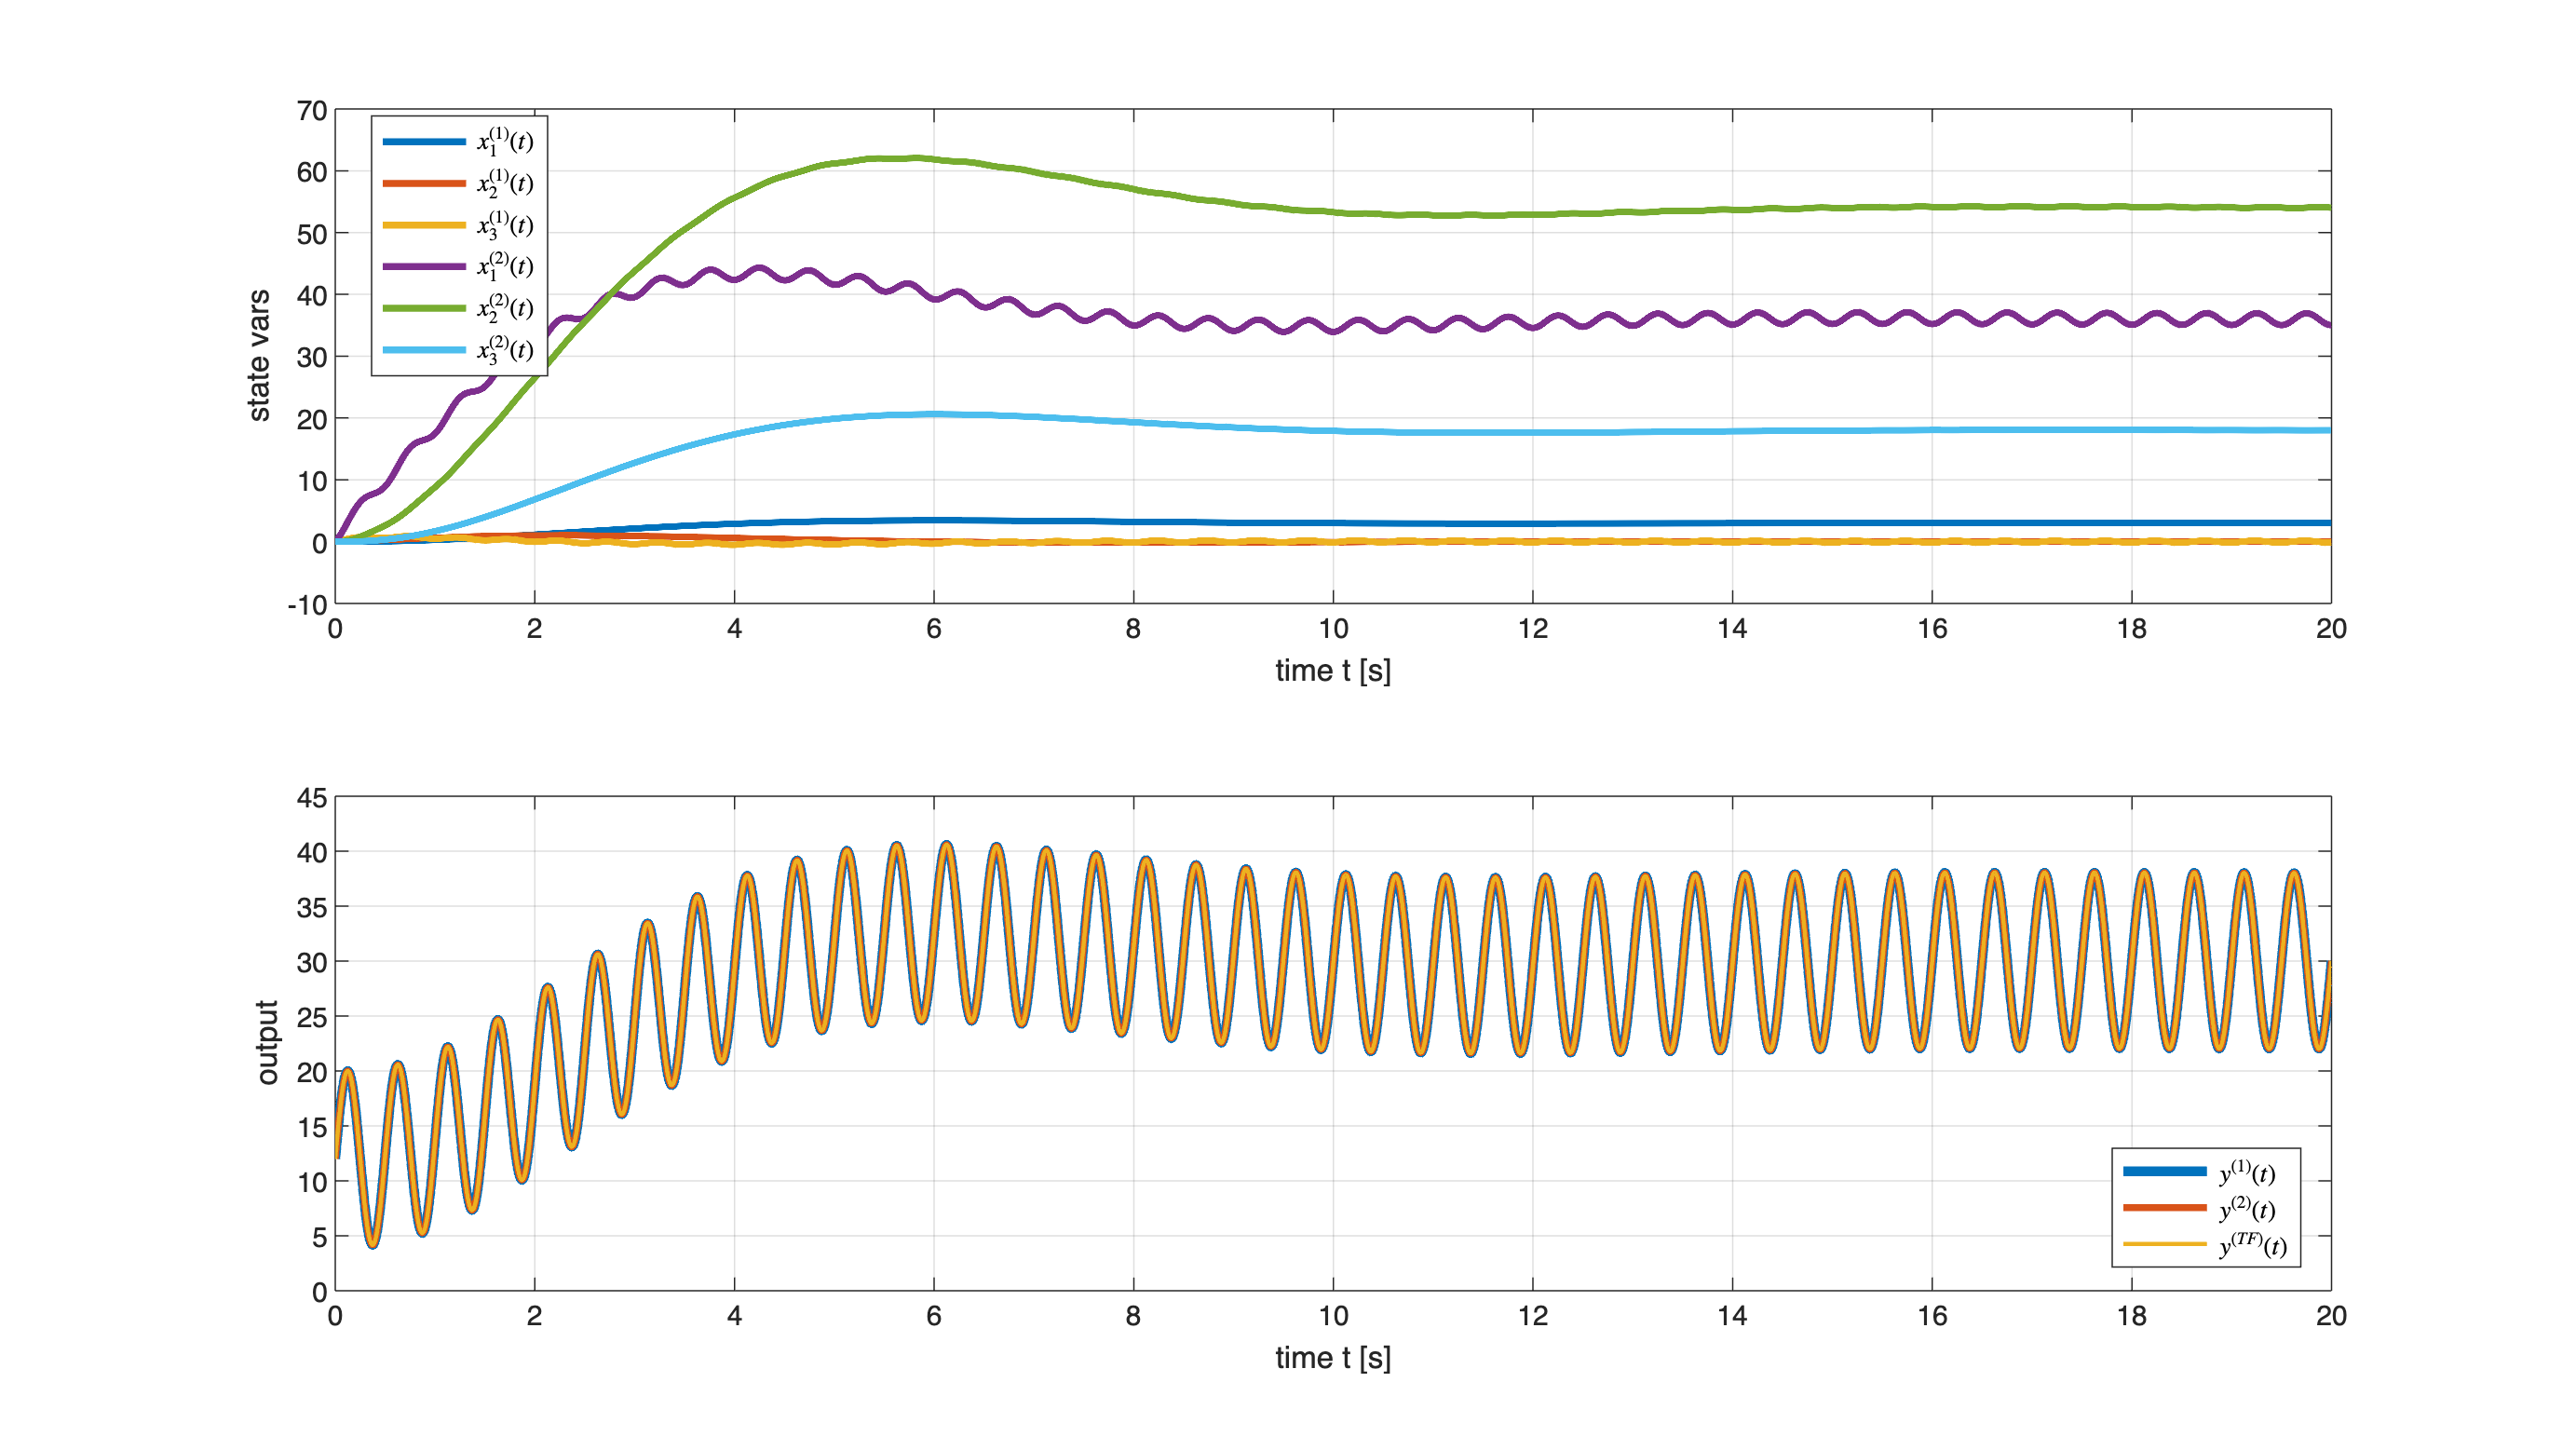

                                
figure('Units','normalized','Position',[0.1, 0.1, 0.9, 0.9]);
subplot(2, 1, 1);
plot(t, x1, 'LineWidth', 2.5);
grid on; hold on
plot(t, x2, 'LineWidth', 2.5);
xlabel('time t [s]'); ylabel('state vars');
legend('$x^{(1)}_{1}(t)$', '$x^{(1)}_{2}(t)$', '$x^{(1)}_{3}(t)$',...
    '$x^{(2)}_{1}(t)$', '$x^{(2)}_{2}(t)$', '$x^{(2)}_{3}(t)$',...
    'Interpreter', 'latex','Location', 'best')

subplot(2,1,2);
plot(t,y1, 'LineWidth', 3.5); % plotting the results
grid on; hold on
plot(t,y2, 'LineWidth', 2.5); 
plot(t,yTF, 'LineWidth', 1.5); 
xlabel('time t [s]'); ylabel('output');
legend('$y^{(1)}(t)$', '$y^{(2)}(t)$','$y^{(TF)}(t)$', ...
    'Interpreter', 'latex','Location', 'best')

#### Final Remarks

- The forced state responses of the two models are different! This is due to the different state variables involved in the two models.

- However, the forced output responses of both state-space models are the same as the forced response calculated using the transfer function model (as expected!).